%Feel free to add code anywhere you find necessary to solve the task.
% as a guide, we have provide recommendation where to add code

## DO NOT CHANGE ANYTHING HERE - Setting up the remote api

vrep=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1); % just in case, close all opened connections
clientID=vrep.simxStart('127.0.0.1',19999,true,true,5000,5);

% connection status
connected = false;

% ultrasonic sensor handles
rangefinder = zeros(1, 6); 
sens_angles = zeros(6,3);
detect_world = zeros(6,3);
bod_sens = zeros(6,3);
angle = zeros(1,6);
% motor handles
leftMotor = 0;
rightMotor = 0;

% sensor reading buffers
detectionState = zeros(1, 6);   % Detection status
detectedPoint = zeros(6, 3);    % Point (vector)
range = zeros(1, 6);                % Euclidean distance
% driving velocity
driveVel = 2;

if (clientID>-1)
    
    connected = true;
    disp('Connected to remote API server');
    
    % get object handles
    [~,leftMotor]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_leftMotor',vrep.simx_opmode_blocking);
    [~,rightMotor]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_rightMotor',vrep.simx_opmode_blocking);
    [~,body]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx',vrep.simx_opmode_blocking);
    % proximity sensor handles
    [~,rangefinder(1)]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_ultrasonicSensor1',vrep.simx_opmode_blocking);
    [~,rangefinder(2)]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_ultrasonicSensor2',vrep.simx_opmode_blocking);
    [~,rangefinder(3)]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_ultrasonicSensor3',vrep.simx_opmode_blocking);
    [~,rangefinder(4)]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_ultrasonicSensor4',vrep.simx_opmode_blocking);
    [~,rangefinder(5)]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_ultrasonicSensor5',vrep.simx_opmode_blocking);
    [~,rangefinder(6)]=vrep.simxGetObjectHandle(clientID,'Pioneer_p3dx_ultrasonicSensor6',vrep.simx_opmode_blocking);
    % initialize proximity sensor reading
    for i = 1:6
    [~,detectionState(i),detectedPoint(i, :),~,~]=vrep.simxReadProximitySensor(clientID,rangefinder(i),vrep.simx_opmode_streaming );
    end
    
    % ADD CODE HERE IF NECESSARY
    
end

Connected to remote API server


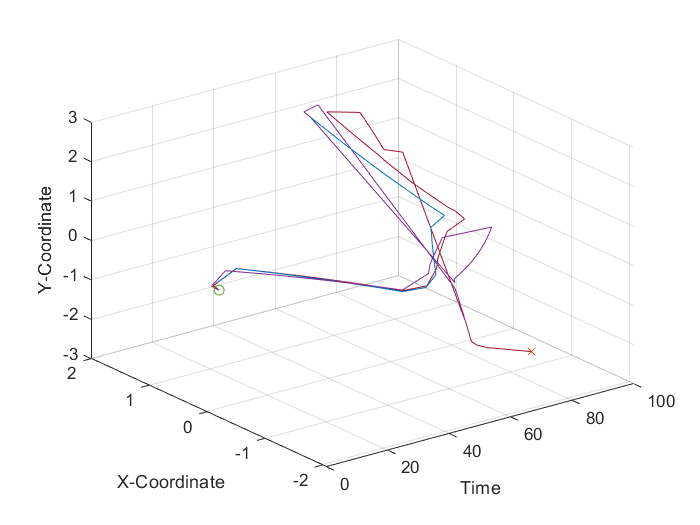


 if (connected)
    clock1=tic;
    i=1;
    pause(4);
    while true
        % run motors
        [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, driveVel, vrep.simx_opmode_blocking);
        [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, driveVel, vrep.simx_opmode_blocking);
        t=toc(clock1);
        [returnCode, posnew]=vrep.simxGetObjectPosition(clientID,body,-1,vrep.simx_opmode_blocking);
        pos_t(i,:) = [posnew(1),posnew(2),t];
        
        % read rangefinders sensors
        for n = 1:6
            [~,detectionState(n),detectedPoint(n, :),~,~]=vrep.simxReadProximitySensor(clientID,rangefinder(n),vrep.simx_opmode_buffer  );
            range(n) = norm(detectedPoint(n, :)); % Euclidean distance to obstacles 
            [returnCode, sens_angles(n,:)]=vrep.simxGetObjectOrientation(clientID, rangefinder(n),-1,vrep.simx_opmode_blocking);
            
            z = [cos(sens_angles(n,3))  sin(sens_angles(n,3)) 0; -sin(sens_angles(n,3)) cos(sens_angles(n,3)) 0; 0 0 1 ];
            y = [cos(sens_angles(n,2))  -sin(sens_angles(n,2)) 0; sin(sens_angles(n,2)) cos(sens_angles(n,2)) 0; 0 0 1 ];
            x = [cos(sens_angles(n,1))  -sin(sens_angles(n,1)) 0; sin(sens_angles(n,1)) cos(sens_angles(n,1)) 0; 0 0 1 ];
            [returnCode, bod_sens(n,:)]=vrep.simxGetObjectPosition(clientID,rangefinder(n),body,vrep.simx_opmode_blocking);
            detect_world(n,:) = (x*y*z*(detectedPoint(n,:).')).' + bod_sens(n,:);
            angle(n) = atan2d(detect_world(n,2),detect_world(n,1));
            % ADD CODE HERE
             while detectionState(n) == 1 && range(n) <=0.4
                  [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 0, vrep.simx_opmode_blocking);
                  [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 0, vrep.simx_opmode_blocking);
                  while detectionState(n) == 1
                      [~,detectionState(n),detectedPoint(n, :),~,~]=vrep.simxReadProximitySensor(clientID,rangefinder(n),vrep.simx_opmode_buffer  );
                      if angle(n) > 0
                         [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 20 , vrep.simx_opmode_blocking);
                         [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, -20, vrep.simx_opmode_blocking);  
                      else
                         [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, -20 , vrep.simx_opmode_blocking);
                         [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 20, vrep.simx_opmode_blocking);  
                      end
                  [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 0 , vrep.simx_opmode_blocking);
                  [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 0, vrep.simx_opmode_blocking);  
                  end
                   [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 40 , vrep.simx_opmode_blocking);
                   [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 40, vrep.simx_opmode_blocking);  
             end

        end
        if (t>90)
            break;
        end
        i=i+1;
    % stop wheels
    [~]=vrep.simxSetJointTargetVelocity(clientID, leftMotor, 0.5, vrep.simx_opmode_blocking);
    [~]=vrep.simxSetJointTargetVelocity(clientID, rightMotor, 0.5, vrep.simx_opmode_blocking);
    end
    plot3(pos_t(:,3),pos_t(:,1),pos_t(:,2));
    hold on; grid on;
    plot3(pos_t(1,3),pos_t(1,1),pos_t(1,2),'o');
    plot3(pos_t(end,3),pos_t(end,1),pos_t(end,2),'x');
    xlabel("Time")
    ylabel("X-Coordinate");
    zlabel("Y-Coordinate");
    % Now close the connection to V-REP:    
    vrep.simxFinish(clientID);
else
    disp('Failed connecting to remote API server');
end

vrep.delete(); % call the destructor!